## **Author: MatNoble_HUST **

## **Date: 2019_6_10**

**Poisson Equation (2D)**


$$-\nabla \cdot(c \nabla u)=f$$


multiply v(x) and integral


$$-\int_{\Omega} \nabla \cdot(c \nabla u) v d x d y=\int_{\Omega} f v d x d y$$


Green's formula


$$\int_{\Omega} \nabla \cdot(c \nabla u) v d x d y=\int_{\partial \Omega}(c \nabla u \cdot \vec{n}) v d s-\int_{\Omega} c \nabla u \cdot \nabla v d x d y$$


then 


$$\int_{\Omega} c \nabla u \cdot \nabla v d x d y-\int_{\partial \Omega}(c \nabla u \cdot \vec{n}) v d s=\int_{\Omega} f v d x d y$$


and $v=0$ on $\partial \Omega$. then


$$\int_{\Omega} c \nabla u \cdot \nabla v d x d y=\int_{\Omega} f_{v} d x d y$$


i. e. **weak formulation**

find $u \in H^{1}(\Omega)$ such that


$$a(u, v)=(f, v)$$
 

for any $v \in H_{0}^{1}(\Omega)
$.

further, **Galerkin formulation**

find $u_{h} \in U_{h}$ such that


$$a\left(u_{h}, v_{h}\right)=\left(f, v_{h}\right)$$



$$\Leftrightarrow \int_{\Omega} c \nabla u_{h} \cdot \nabla v_{h} d x d y=\int_{\Omega} f v_{h} d x d y$$


for any $v_{h} \in U_{h}^{0}$.

Tb_test =      1     2     2     3     3     4     4     5     5     6     6     7     7     8     8     9     9    10    10    11    11    12    12    13    13    14    14    15    15    16    16    17    17    18    18    19    19    20    20    21    21    22    22    23    23    24    24    25    25    26
    34    34    35    35    36    36    37    37    38    38    39    39    40    40    41    41    42    42    43    43    44    44    45    45    46    46    47    47    48    48    49    49    50    50    51    51    52    52    53    53    54    54    55    55    56    56    57    57    58    58
     2    35     3    36     4    37     5    38     6    39     7    40     8    41     9    42    10    43    11    44    12    45    13    46    14    47    15    48    16    49    17    50    18    51    19    52    20    53    21    54    22    55    23    56    24    57    25    58    26    59


solution1 =     0.4060
    0.3925
    0.3774
    0.3606
    0.3421
    0.3219
    0.3000
    0.2763
    0.2510
    0.2241


error_max1 = 4.3521e-04

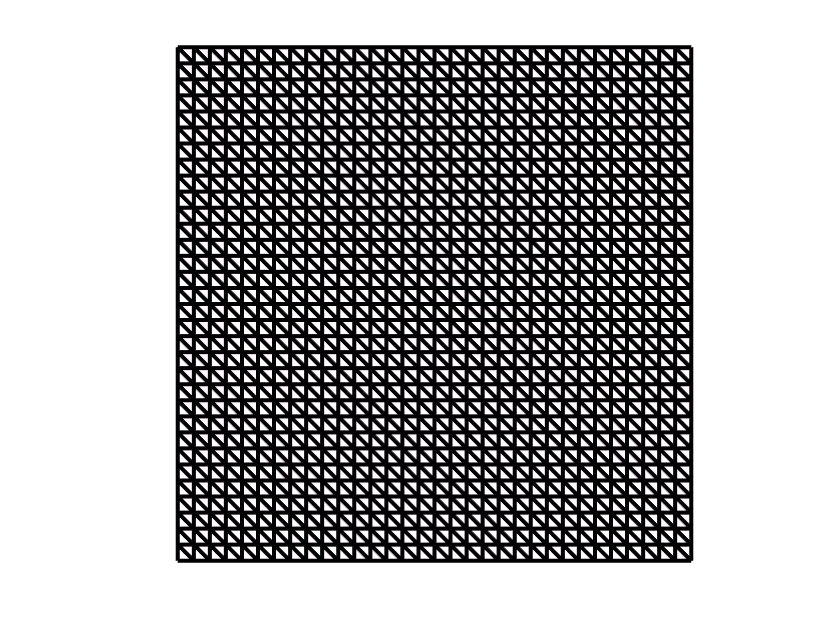

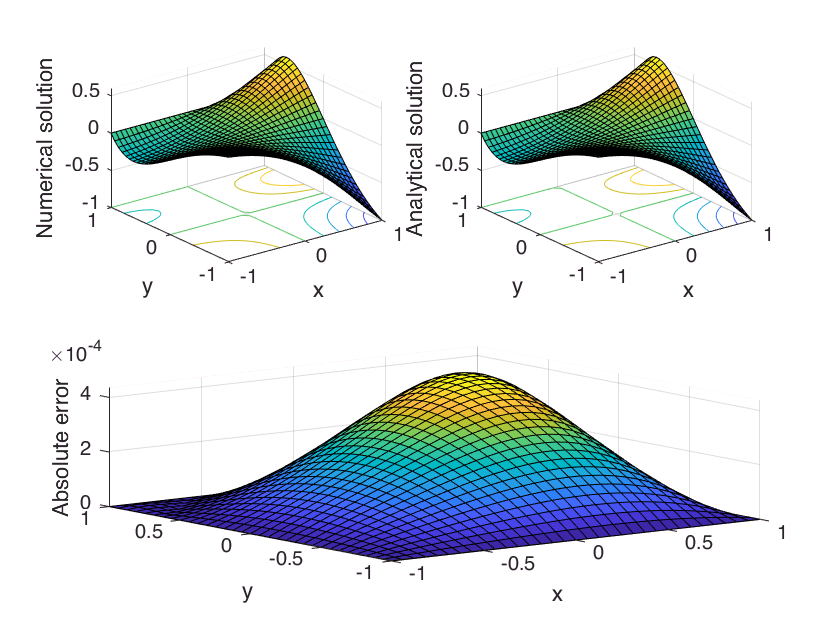

% [solution1, error_max1] = Poisson_2D(left, right, top, bottom,...
%                                      u, u_x, c, f, nx, ny,...
%                                      p, basis_type, Boundary_type)
% number of mesh elements
% p : Degree of distortion
% basis_type : 
              % 201 : 2D linear
              % 202 : 2D quadratic

%%%%%% 
u = @(x, y)(x.*y.*(1-x/2).*(1-y).*exp(x+y));

u_xy = @(x)(-exp(x-1));

c = @(x, y)((x+y)*0 + 1);

f = @(x, y)(-y*(1-y)*(1-x-(x^2)/2)*exp(x+y) - x*(1-x/2)*(-3*y-y^2)*exp(x+y));
%%%%%% 

%%%%%% Example 1
left = -1;  right = 1;
bottom = -1;  top = 1;
nx = 32;    ny = 52;
p = 0; 
basis_type = 201; % 2D linear
Boundary_type = [1, 1, 1, 1]; % Neumann
[solution1, error_max1] = Poisson_2D(left, right, top, bottom,...
                                     u, u_xy, c, f, nx, ny,...
                                     p, basis_type, Boundary_type)


% %%%%%% Example 2
% left = -1;  right = 1;
% bottom = -1;  top = 1;
% nx = 4;    ny = 5;
% p = 0; 
% basis_type = 202; % 2D linear
% Boundary_type = [1, 1, 1, 1]; % Neumann
% [solution2, error_max2] = Poisson_2D(left, right, top, bottom,...
%                                      u, u_xy, c, f, nx, ny,...
%                                      p, basis_type, Boundary_type)